## **Theoretical Power Production**

Define latitude of the solar panelsand decleration of the sun

lat = 42 + 17/60;
dec = 23.50;

Convertion from degrees to radians

lat = lat * pi/180;
dec= deg2rad(dec);

t = 5.5:0.25:20;
LST = t - 1 + 14.6/60;

Determine  the amaount of solar irridiance on the solar panels

 $_{panel} = $_{inc}\sin(\alpha), 

sunangle = sin(dec)*sin(lat)+ cos(dec)*cosd(15*(LST-12));
S_inc = 1.4883*0.7.^(sunangle.^-0.678);

Calculate the final theoretical production for entire solar panel array

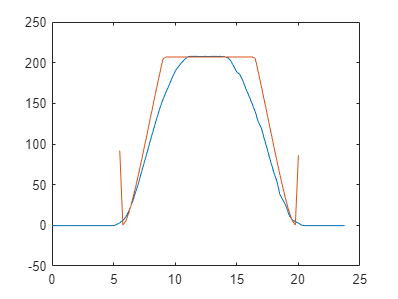

production_theory = min(270 *S_inc.*sunangle,207);
%plot(t,production_theory);
xlabel('Time of Day');
ylabel('Energy Production (kW)');

%plot(Production.Timestamp,Production.AH3);
    
June2018= reshape(Production.AH3,96,30 );
dayofInterest = June2018(:,26);
tfullday = 0:0.25:23.75;
plot(tfullday,dayofInterest,t,production_theory)